**Generating the simple quad matrices**

clear
rng(1,'twister');
close all  
% Generate a random sym pos def matrix

n = 200;
B = rand(n,n);
% get a random symmetric matrix
B = 0.5*(B + B');
[V,D] = eig(B);
%make its n eigs > 0 by picking from uniform pd [1,n^2]
Dp = randi(n^2,n,1);
% Dp = [1:n];
% Dp = [1,1,1,5,5,5,5,10,10,10];
A = V * diag(Dp) * V';
%prepare a col vector b for use in the quadratic functional
b_orig = rand(n,1);
b = b_orig + 0.00 * rand(n,1);
% Prepare the quadratic functional and sim params

disp(["Condition no of A -" num2str(cond(A)) "Max eigval of A - " num2str(max(eig(A))) "Min eigval - " num2str(min(eig(A)))])

    "Condition no of A -"    "458.3678"    "Max eigval of A - "    "39878"    "Min eigval - "    "87"




f = @(x) 0.5 * x' * A * x - b' * x;                 
gradf = @(x) A * x - b;
hess = A;   
x_true = A\b_orig;

**Standard bcsstm matrix**

% clear
% % downoad the standard matrix as a .mat file from "https://sparse.tamu.edu/HB/bcsstm07" and put in same directory as this code file, then run
% testm = load("bcsstm07.mat");
% A = testm.Problem.A;
% % disp(["Condition no of A -" num2str(cond(A)) "Max eigval of A - " num2str(max(eig(A))) "Min eigval - " num2str(min(eig(A)))])
% 
% n = size(A,1);
% x_true = ones(n,1);
% b = A*x_true;
% 
% syms x [n,1] 'real'
% f = 0.5 * x' * A * x - b' * x;  
% fh = matlabFunction(f, "Vars", {x}, "Optimize",false);
% 
% % Hardcoding gradf
% % gradf = A * x - b;
% % gh = matlabFunction(gradf, "Vars", {x}, "Optimize",false);
% 
% % Getting jacobian
% gradientf = jacobian(f,x)';
% gradh = matlabFunction(gradientf, "Vars", {x}, "Optimize",false);
% % Obtaining hessian - takes 15 minutes 
% hessianf = jacobian(jacobian(f,x)', x);
% hh = matlabFunction(hessianf, "Vars", {x}, "Optimize",false);

**Styblinski demo**

% clear
% syms x [2,1] 'real'
% f = 0.5*(x(1)^4-16*x(1)^2+5*x(1)) + 0.5*(x(2)^4-16*x(2)^2+5*x(2));
% fh = matlabFunction(f, "Vars", {reshape(x,[],1)}, "Optimize",false);
% 
% gradientf = jacobian(f,x)';
% gradh = matlabFunction(gradientf, "Vars", {x}, "Optimize",false);
% 
% hessianf = jacobian(gradientf, x)
% hh = matlabFunction(hessianf, "Vars", {x}, "Optimize",false);

**SD comparison (later for best starting point)**

x0 = rand(n,1);
x1 = x0;
max_sd_iter = 50;
tol = 1e-6; 
x_SD = [x1];
gf = gradf(x1);
sd_gf_log = [norm(gf)];
%set initialization params
k_SD = 0;

while norm(gf) > tol && k_SD < max_sd_iter
    disp(['SD: k_SD=' num2str(k_SD) ', norm_gf=' num2str(norm(gf))]);
    alpha = gf'*gf/(gf'*A*gf); 
    x_new = x1 + alpha * (-gf); 
    gf = gradf(x_new); 
    sd_gf_log = [sd_gf_log, norm(gf)];
    x1 = x_new;
    k_SD = k_SD+1;   
    x_SD = [x_SD, x1];
end

SD: k_SD=0, norm_gf=178744.6923
SD: k_SD=1, norm_gf=50992.0887
SD: k_SD=2, norm_gf=15216.7974
SD: k_SD=3, norm_gf=8689.5566
SD: k_SD=4, norm_gf=5783.4629
SD: k_SD=5, norm_gf=4679.9226
SD: k_SD=6, norm_gf=3409.2218
SD: k_SD=7, norm_gf=2975.5435
SD: k_SD=8, norm_gf=2297.8156
SD: k_SD=9, norm_gf=2107.8756
SD: k_SD=10, norm_gf=1686.6435
SD: k_SD=11, norm_gf=1592.4273
SD: k_SD=12, norm_gf=1300.1342
SD: k_SD=13, norm_gf=1248.1859
SD: k_SD=14, norm_gf=1031.8003
SD: k_SD=15, norm_gf=1001.5622
SD: k_SD=16, norm_gf=835.3315
SD: k_SD=17, norm_gf=817.7487
SD: k_SD=18, norm_gf=686.991
SD: k_SD=19, norm_gf=677.3938
SD: k_SD=20, norm_gf=572.7072
SD: k_SD=21, norm_gf=568.3557
SD: k_SD=22, norm_gf=483.2863
SD: k_SD=23, norm_gf=482.4324
SD: k_SD=24, norm_gf=412.3728
SD: k_SD=25, norm_gf=413.8483
SD: k_SD=26, norm_gf=355.4333
SD: k_SD=27, norm_gf=358.44
SD: k_SD=28, norm_gf=309.1742
SD: k_SD=29, norm_gf=313.1628
SD: k_SD=30, norm_gf=271.1739
SD: k_SD=31, norm_gf=275.7668
SD: k_SD=32, norm_gf=239.6353
SD:

**IPG Parameters and method**

% Initial parameters
max_iter = 50;
tol = 1e-6; 

% n=2;
% x0 = [-1,-1]';
x = x0;
x_IPG = [x];

% setting parameters
gf = gradf(x);
gf_log = [norm(gf)];
k = 0;
Id = eye(n);

alpha = 10; % watch out for it's clipping later in the loop
beta = 5;
delta = 1;

% p logging
hes = A;
p_log = [norm(Id-alpha*(hes + beta*Id))];

% K = inv(A + beta*Id);
K = zeros(n);
K_star = inv(A + beta*Id);
kmat0 = norm(K - K_star);
kmat_log = [kmat0];

while norm(gf) > tol && k < max_iter

    disp(['IPG: k=' num2str(k) ', norm_gf=' num2str(norm(gf))]);
    gf = gradf(x);    
    hes = A;    

    % potential check for alpha, beta conditions
    e = eig(hes);
    alpha_lim = 1 / (max(e) + beta);
    if alpha > alpha_lim
        alpha = alpha_lim - alpha_lim/10;
    end
    
    beta_lim = -min(e);    
    if beta < beta_lim
        beta = (beta_lim + beta_lim/10);
    end  

    % disp([' alpha ' num2str(alpha) ' beta ' num2str(beta)])
    
    % testing alpha_lim and beta_lim
    % e = eig(hes);
    % disp([' max eigval ' num2str(max(e)) ' min eigval ' num2str(min(e))])
    % alpha_lim = 1 / (max(e) + beta);
    % beta_lim = -min(e);
    % disp(['alpha_lim = ' num2str(alpha_lim) ' beta_lim = ' num2str(beta_lim)])

    R = (hes + beta*Id)*K - Id;
    x_new = x - delta*(K*gf);
    K = K - alpha*R;
    
    % logging distance of current K from K_star
    kmat_n = norm(K - K_star);
    kmat_log = [kmat_log, kmat_n];

    gf_log = [gf_log, norm(gf)];
    p_log = [p_log, norm(Id-alpha*(hes + beta*Id))];

    x = x_new;
    k = k+1;

    x_IPG = [x_IPG, x];

end

IPG: k=0, norm_gf=178744.6923
IPG: k=1, norm_gf=178744.6923
IPG: k=2, norm_gf=178744.6923
IPG: k=3, norm_gf=81426.6505
IPG: k=4, norm_gf=23655.7275
IPG: k=5, norm_gf=6352.7419
IPG: k=6, norm_gf=3102.3578
IPG: k=7, norm_gf=1842.601
IPG: k=8, norm_gf=1179.3786
IPG: k=9, norm_gf=789.3535
IPG: k=10, norm_gf=538.1937
IPG: k=11, norm_gf=371.4799
IPG: k=12, norm_gf=260.5474
IPG: k=13, norm_gf=186.4392
IPG: k=14, norm_gf=136.3246
IPG: k=15, norm_gf=101.9371
IPG: k=16, norm_gf=78.0802
IPG: k=17, norm_gf=61.3897
IPG: k=18, norm_gf=49.5619
IPG: k=19, norm_gf=40.9745
IPG: k=20, norm_gf=34.5117
IPG: k=21, norm_gf=29.4482
IPG: k=22, norm_gf=25.3393
IPG: k=23, norm_gf=21.9224
IPG: k=24, norm_gf=19.0422
IPG: k=25, norm_gf=16.6016
IPG: k=26, norm_gf=14.5331
IPG: k=27, norm_gf=12.7842
IPG: k=28, norm_gf=11.3098
IPG: k=29, norm_gf=10.069
IPG: k=30, norm_gf=9.0245
IPG: k=31, norm_gf=8.1424
IPG: k=32, norm_gf=7.3926
IPG: k=33, norm_gf=6.7489
IPG: k=34, norm_gf=6.1897
IPG: k=35, norm_gf=5.697
IPG: k=36, nor

% plot(log(p_log),'b','LineWidth',1); grid;
% xlabel('iters');
% ylabel('p history');title('IPG convergence')
% 
% z = 0.5*(x.^4-16*x.^2+5*x)+0.5*(y.^4-16*y.^2+5*y);

% [x,y] = meshgrid(-4.0:0.2:4.0,-4.0:0.2:4.0);
% z = 0.5*(x.^4-16*x.^2+5*x)+0.5*(y.^4-16*y.^2+5*y);

% figure(1)
% surfl(x,y,z)
% axis([-4 4 -4 4 -80 20])
% xlabel('x1'), ylabel('x2'), zlabel('z')

% x1 = x_IPG(1,:);
% y1 = x_IPG(2,:);
% contour(-4.0:0.2:4.0,-4.0:0.2:4.0,z,15);
% xlabel('x1'), ylabel('x2')
% hold on
% plot(x1,y1,x1,y1,'o')
% xlabel('x1'), ylabel('x2')
% hold off

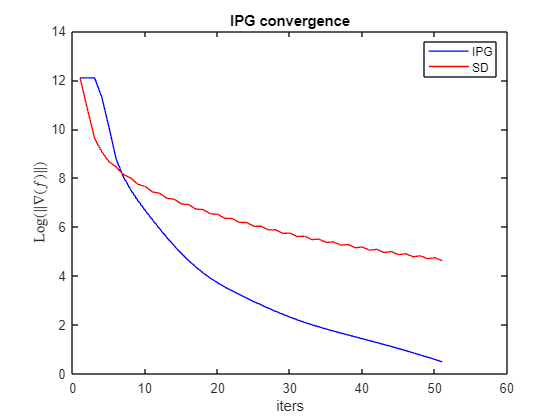

% % subplot(2,1,1);
% Plotting only IPG
% plot(log(gf_log),'b','LineWidth',2); grid;
% xlabel('iters');
% ylabel('Log($\|\nabla(f)\|$)','Interpreter','latex');title('IPG convergence');
% disp(log(gf_log(end)))
% disp(log(sd_gf_log(end)))

% Plotting both IPG and SD
plot(log(gf_log),'b','LineWidth',1); grid;
hold on
plot(log(sd_gf_log),'r','LineWidth',1); grid;
hold off
legend('IPG', 'SD')
xlabel('iters');
ylabel('Log($\|\nabla(f)\|$)','Interpreter','latex');title('IPG convergence');

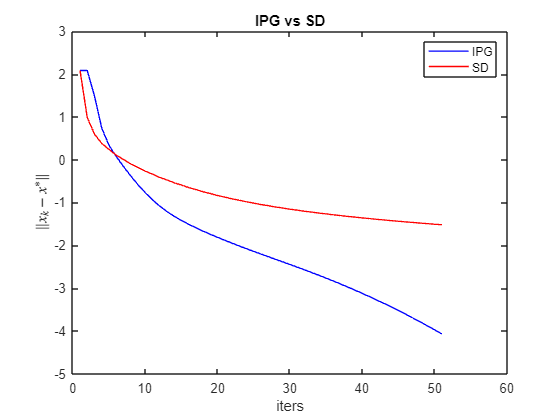

% subplot(2,1,2);
plot(log(vecnorm(x_IPG-repmat(x_true,[1,1+k]))),'b','LineWidth',1); grid;
hold on
plot(log(vecnorm(x_SD-repmat(x_true,[1,1+k_SD]))),'r','LineWidth',1); grid;
hold off
legend('IPG', 'SD')
ylabel('$\|x_k-x^*\|$','Interpreter','latex'); xlabel('iters'); title('IPG vs SD');

**Testing convergence of K to K***

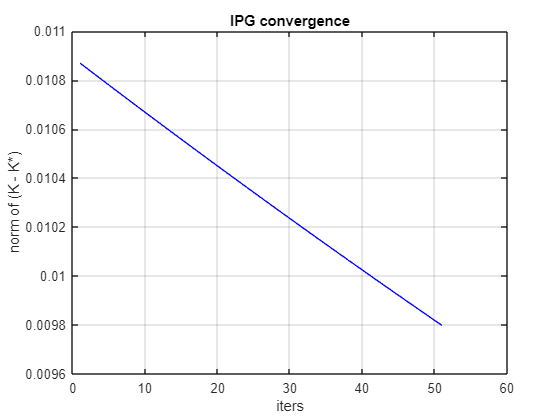

plot((kmat_log),'b','LineWidth',1); grid;
xlabel('iters');
ylabel('norm of (K - K*)');title('IPG convergence');

**Rate of Convergence Test**

% x_diff = vecnorm(x_IPG-repmat(x_true,[1,1+k]));
% x_shift = x_diff(2:end);
% r_seq = x_shift ./ x_diff(1:end-1);
% 
% sd_x_diff = vecnorm(x_SD-repmat(x_true,[1,1+k_SD]));
% sd_x_shift = sd_x_diff(2:end);
% sd_r_seq = sd_x_shift ./ sd_x_diff(1:end-1);
% 
% plot((r_seq),'b','LineWidth',1); grid;
% hold on
% plot((sd_r_seq),'r','LineWidth',1); grid;
% hold off
% xlabel('iters');
% ylabel('rate');
% legend("IPG", "SD");
% 
% % title('IPG rate of convergence');

